format long 
syms y(x) f_d(s,t,z) g_d(s,t,z)

% find the exact solutions function first 
Dy = diff(y);

% plug in the ode equation
ode = diff(y,x,2) + 0.25*diff(y,x,1) == 8;

% input the ode boundary conditions
cond1 = y(0) == 0;
cond2 = y(10) == 0;

% solve for the pde
conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(x) = 32\,x+\frac{320\,{\mathrm{e}}^{\frac{5}{2}-\frac{x}{4}}}{{\mathrm{e}}^{5/2}-1}-\frac{64\,\left(3\,{\mathrm{e}}^{5/2}+2\right)}{{\mathrm{e}}^{5/2}-1}-128$$

Compute the shooting method

% set the step size
h = 1;

% set the range for the data points
x = 0:h:10;

% boundary conditions
y_0 = 0;
y_10 = 0;

% input the derrivative functions associated the ODE 
f_d(s,t,z) = z;
g_d(s,t,z) = 8 - z/4;

% guess random points to start so we can interpolate a distance
yd_top = 1;
y_top = 0;

yd_bottom = 0;
y_bottom = 0;
while 1
    % do the process for the top pt
    % create the list of y, z points that will be used and insert the ICs
    y_e_top = zeros(length(x),1);
    y_e_top(1) = y_0;
    
    z_e_top = zeros(length(x),1);
    z_e_top(1) = yd_top;
    
    for i=1:length(x)-1
        y_e_top(i+1) = y_e_top(i) + h*f_d(x(i),y_e_top(i),z_e_top(i));
        z_e_top(i+1) = z_e_top(i) + h*g_d(x(i),y_e_top(i),z_e_top(i));
    end
    y_top = y_e_top(length(x));
    
    % repeat for bottom point
    % create the list of y, z points that will be used and insert the ICs
    y_e_bottom = zeros(length(x),1);
    y_e_bottom(1) = y_0;
    
    z_e_bottom = zeros(length(x),1);
    z_e_bottom(1) = yd_bottom;
    
    for i=1:length(x)-1
        y_e_bottom(i+1) = y_e_bottom(i) + h*f_d(x(i),y_e_bottom(i),z_e_bottom(i));
        z_e_bottom(i+1) = z_e_bottom(i) + h*g_d(x(i),y_e_bottom(i),z_e_bottom(i));
    end
    y_bottom = y_e_bottom(length(x));
    
    if y_top*y_bottom < 0
        break;
    else
        yd_bottom = yd_bottom - 10;
        yd_top = yd_top + 10;
    end
end

p = yd_top + (yd_bottom-yd_top)*(y_10 - y_top)/(y_bottom-y_top)

p =  -52.773917235204294


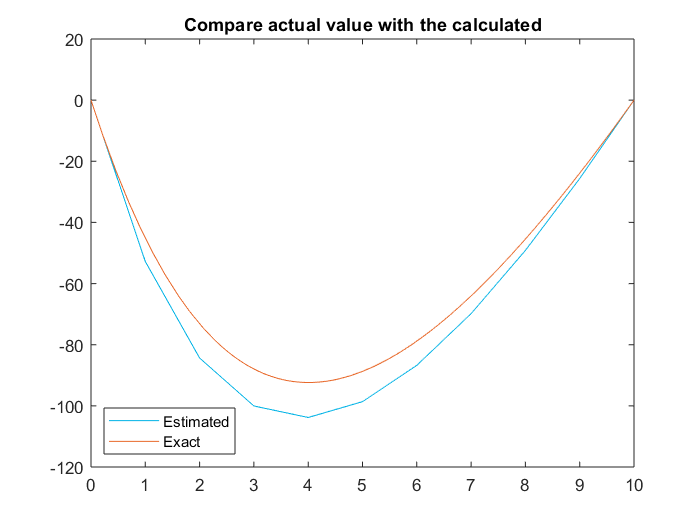

% create the list of y, z points that will be used and insert the ICs
y_e = zeros(length(x),1);
y_e(1) = y_0;

z_e = zeros(length(x),1);
z_e(1) = p;

for i=1:length(x)-1
    y_e(i+1) = y_e(i) + h*f_d(x(i),y_e(i),z_e(i));
    z_e(i+1) = z_e(i) + h*g_d(x(i),y_e(i),z_e(i));
end

plot(x,y_e,'Color',[0,0.7,0.9])
hold on 
fplot(ySol,[0,10],'Color',[0.9100,0.4100,0.1700])
legend({'Estimated','Exact'},'Location','southwest')
title('Compare actual value with the calculated')
hold off

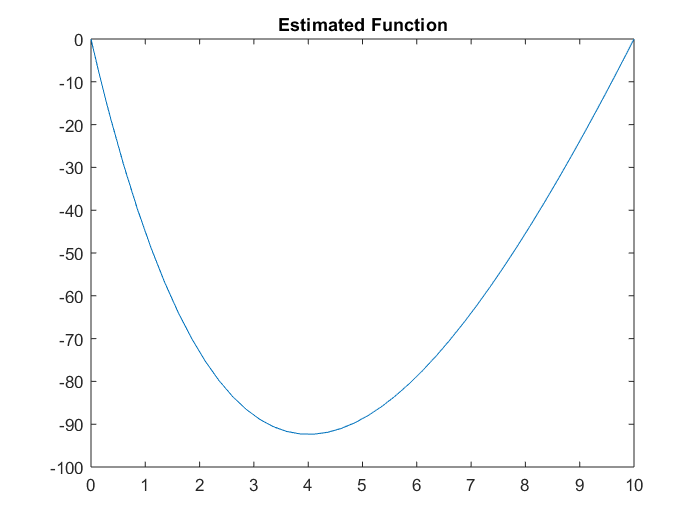

x =  -55.154046402018011


y =      1.776356839400250e-14


z =      1




% DONT NEEED
x0 = 0.5;
% compute the fzero of the function computed 
[x,y,z] = fzero(@F,x0)

function [f,x_coord,y_coord]=F(s) % define the shooting functions
% using the matlab ode45 
[x,y] = ode45(@de,[0 10], [0 s]);

% use the initial condition for the end boundary conditio
y_10 = 0;
f = y(end,1) - y_10;
% plot the output
% hold on
plot(x,y(:,1))
title('Estimated Function')
x_coord = x;
y_coord = y(:,1);
end

% systems of differential equations
function y=de(t,x)
% since second order find the 2 functions for he DE 
y = zeros(2,1);

y(1) = x(2);
y(2) = 8 - x(2)/4;
end





